# 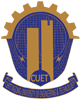

#  Chittagong University of Engineering & Technology

***Department of Electrical and Electronic Engineering***

**Control System Engineering**

**MD. SAYEDUL**

**ID:1702079**

**u1702079@student.cuet.ac.bd**

Reference Book:

- MATLAB for Control Engineers, **Katsuhiko Ogata**, *University of Minnesota, *[Prentice Hall](https://www.pearson.com/us/higher-education.html), 2008, ISBN: 978-0-13-615077-0

- Control Systems Engineering 7th Edition by [Norman S. Nise](https://www.amazon.com/Norman-S-Nise/e/B001H6N2G0/ref=dp_byline_cont_book_1) 

- Automatic Control Systems, Tenth Edition [Dr. Farid Golnaraghi](javascript://) [Dr. Benjamin C. Kuo](javascript://) ISBN:9781259643835 Publication Date & Copyright:2017  McGraw-Hill Education

# Transient Response Analysis

## Partial fraction expansion


$$\frac{C(s)}{R(s)}=\frac{2s^3+5s^2+3s+6}{s^3+6s^2+11s+6}$$


num=[2 5 3 6];
den=[1 6 11 6];
[r p k]=residue(num,den)

r =    -6.0000
   -4.0000
    3.0000


p =    -3.0000
   -2.0000
   -1.0000


k = 2

So the Partial fraction is $\frac{C(s)}{R(s)}=\frac{-6}{s+3}+\frac{-4}{s+2}+\frac{3}{s+1}+2$

## Partial Fraction to Polynomial Equation

r=[-6;-4;3];
p=[-3;-2;-1];
k=2;
[num,den]=residue(r,p,k)

num =      2     5     3     6


den =      1     6    11     6


printsys(num,den,'s')

 
num/den = 
 
   2 s^3 + 5 s^2 + 3 s + 6
   -----------------------
    s^3 + 6 s^2 + 11 s + 6


So the equation is $\frac{C(s)}{R(s)}=\frac{2s^3+5s^2+3s+6}{s^3+6s^2+11s+6}$

## Zeros and pole of C(s)/R(s)

 
$$$\frac{C(s)}{R(s)}=\frac{4s^2+16s+12}{s^4+12s^3+44s^2+48s}$$$


num=[4 16 12];
den=[1 12 44 48 0];
[z p k]=tf2zp(num,den)

z =     -3
    -1


p =          0
   -6.0000
   -4.0000
   -2.0000


k = 4

## Zeros(z) Pole(p) Gain(k) to Transfer Function

z=[-3;-1];
p=[0;-6;-4;-2];
k=4;
[num,den]=zp2tf(z,p,k)

num =      0     0     4    16    12


den =      1    12    44    48     0


So the equation is $$\frac{C(s)}{R(s)}=\frac{4s^2+16s+12}{s^4+12s^3+44s^2+48s}$$

## Obtain the Zeros (z) Pole(p) ane Gain(k) of the system  $\frac{C(s)}{R(s)}=\frac{5s^3+30s^2+55s +30}{s^3+9s^2+33s+65}$

num=[5 30 55 30];
den=[1 9 33 65];
[z p k]=tf2zp(num,den)

z =    -3.0000
   -2.0000
   -1.0000


p =   -5.0000 + 0.0000i
  -2.0000 + 3.0000i
  -2.0000 - 3.0000i


k = 5

## Obtain the system from Zeros Pole and Gain

z=[-3;-2;-1];
p=[-5;-2+3*j;-2-3*j];
k=5;
[num,den]=zp2tf(z,p,k)

num =      5    30    55    30


den =      1     9    33    65


printsys(num,den,'s')

 
num/den = 
 
   5 s^3 + 30 s^2 + 55 s + 30
   --------------------------
     s^3 + 9 s^2 + 33 s + 65


## Obtain the Inverse Laplace transform $F(s)=\frac{s^5+8s^4+23s^3+35s^2+28s+3}{s^3+6s^2+8s}$

num3=[1 8 23 35 28 3];
den3=[1 6 8 0];
[r p k]=residue(num3,den3)

r =     0.3750
    0.2500
    0.3750


p =     -4
    -2
     0


k =      1     2     3


So the partial fraction equation is $F(s)=s^2+2s+3+\frac{0.375}{s+4}+\frac{0.25}{s+2}+\frac{0.375}{s}$

Here we obtain $s^2+2s+3$ due to k=[1 2 3]

## Polynomial Roots


$$D(s)=s^3+2s^2+3s+4$$


d=[1 2 3 4]

d =      1     2     3     4


r=roots(d)

r =   -1.6506 + 0.0000i
  -0.1747 + 1.5469i
  -0.1747 - 1.5469i


d=poly(r)

d =     1.0000    2.0000    3.0000    4.0000


## Transfer Function to State Space


$$\frac{C(s)}{R(s)}=\frac{10s+10}{s^3+6s^2+5s+10}$$


num=[10 10];
den=[1 6 5 10];
[A,B,C,D]=tf2ss(num,den)

A =     -6    -5   -10
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0    10    10


D = 0

## Transformation from state space to transfer function

The Command is [num den]=ss2tf(A,B,C,D,iu)

iu must be specified for more than one input.If the system has three input (u1,u2,u3) then iu must be either 1,2 or 3wher 1 implies u1, 2 implies u2 and 3 implies u3


$$\frac{d}{dt} \pmatrix{x_1(t) \cr x_2(2)\cr x_3(t)}=\pmatrix{0 & 1 & 0 \cr 0 & 0 & 1 \cr -5.008 & -25.1026 & -5.03247} \pmatrix{x_1(t) \cr x_2(t) \cr x_3(t)}+\pmatrix{0 \cr 25.04 \cr -121.005}u(t)$$



$$y=[\matrix{1 & 0 & 0}] \pmatrix{x_1(t) \cr x_2(t) \cr x_3(t)}$$


A=[0 1 0;0 0 1;-5.008 -25.1026 -5.03247];
B=[0;25.04;-121.005];
C=[1 0 0];
D=[0];
[num,den]=ss2tf(A,B,C,D,1)

num =          0         0   25.0400    5.0080


den =     1.0000    5.0325   25.1026    5.0080


printsys(num,den,'s')

 
num/den = 
 
              25.04 s + 5.008
   ------------------------------------
   s^3 + 5.0325 s^2 + 25.1026 s + 5.008


## Multiple input Single output State space to Transfer Function


$$\frac{d}{dt} \pmatrix{x_1(t) \cr x_2(t)}=\pmatrix{0 &1 \cr -2 & -3} \pmatrix{x_1(t) \cr x_2(t)}+\pmatrix{1 & 0 \cr 0& 1}\pmatrix{u_(t) \cr u_2(t)}$$



$$y(t)=[\matrix{1 & 0}]\pmatrix{x_1(t) \cr x_2(t)}+[\matrix{0&0}]\pmatrix{u_1(t) \cr u_2(t)}$$


Which has two input and one ouyput.Two transfer function may be obtained for this system,One relates the output y(t) to input $u_1(t)$ and other relates output y(t) to input $u_2(t)$.When considering input $u_1(t)$ we assume that input $u_2(t)$ is zero and vice versa.

A=[0 1;-2 -3];
B=[1 0;0 1];
C=[1 0];
D=[0 0]; %B & D matrix must have the same number of colomns
[num den]=ss2tf(A,B,C,D,1) %here 1 for input u1(t)

num =      0     1     3


den =      1     3     2


printsys(num,den)

 
num/den = 
 
       s + 3
   -------------
   s^2 + 3 s + 2



$$\frac{Y(s)}{U_1(s)}=\frac{s+3}{s^2+3s+2}$$


[num2,den2]=ss2tf(A,B,C,D,2) %here 2 for input u2(t)

num2 =      0     0     1


den2 =      1     3     2


printsys(num2,den2)

 
num/den = 
 
         1
   -------------
   s^2 + 3 s + 2



$$\frac{Y(s)}{U_2(s)}=\frac{1}{s^2+3s+2}$$


## Multiple input Multiple output State space to Transfer Function

 
$$\frac{d}{dt} \pmatrix{x_1(t) \cr x_2(t)}=\pmatrix{0 &1 \cr -25 & 4} \pmatrix{x_1(t) \cr x_2(t)}+\pmatrix{1 & 1 \cr 0& 1}\pmatrix{u_(t) \cr u_2(t)}$$



$$\pmatrix{y(t) \cr y_2(t)}=\pmatrix{1 & 0 \cr 0&1} \pmatrix{x_1(t) \cr x_2(t)}+\pmatrix{0&0 \cr 0 & 0}\pmatrix{u_1(t) \cr u_2(t)}$$


A=[0 1;-25 4];
B=[1 1;0 1];
C=[1 0;0 1];
D=[0 0;0 0];
[num1,den_r]=ss2tf(A,B,C,D,1)

num1 =      0     1    -4
     0     0   -25


den1 =     1.0000   -4.0000   25.0000


printsys(num1,den_r)

 
num(1)/den = 
 
        s - 4
   --------------
   s^2 - 4 s + 25
 
num(2)/den = 
 
         -25
   --------------
   s^2 - 4 s + 25


So  $\frac{Y_1(s)}{U_1(s)}=\frac{s-4}{s^2-4s+25}$ 

and  $\frac{Y_2(s)}{U_1(s)}=\frac{-25}{s^2-4s+25}$

[num2,den2]=ss2tf(A,B,C,D,2)

num2 =          0    1.0000   -3.0000
         0    1.0000  -25.0000


den2 =     1.0000   -4.0000   25.0000


printsys(num2,den2)

 
num(1)/den = 
 
       1 s - 3
   --------------
   s^2 - 4 s + 25
 
num(2)/den = 
 
       s - 25
   --------------
   s^2 - 4 s + 25


So $\frac{Y_1(s)}{U_2(s)}=\frac{s-3}{s^2-4s+25}$

and $\frac{Y_2(s)}{U_2(s)}=\frac{s-25}{s^2-4s+25}$

## MATLAB Representation of System in Blick Diagram Form

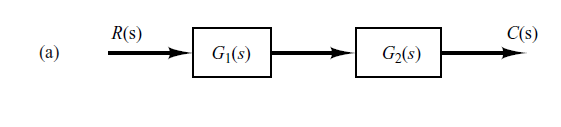

In this figure system $G_1(s)$ (which is represenr by sys1) and $G_2(s)$ (which is represenr by sys2) are Series connected system.

sys1=tf(num1,den1)

sys2=tf(num2,den2)

Then the series connected system can be given by

sys=series(sys1,sys2)

The system's numerator and denominator can also be given by

[num,den]=series(num1,den1,num2,den2)


$$G_1(s)=\frac{10}{s^2+2s+10}$$


               
$$G_2(s)=\frac{5}{s+5}$$


num1=[10];
den_r=[1 2 10];
num2=[5];
den2=[1 5];
sys1=tf(num1,den_r);
sys2=tf(num2,den2);
syss=series(sys1,sys2)


syss =
 
            50
  -----------------------
  s^3 + 7 s^2 + 20 s + 50
 
Continuous-time transfer function.



[num,den]=series(num1,den_r,num2,den2);
printsys(num,den)

 
num/den = 
 
              50
   -----------------------
   s^3 + 7 s^2 + 20 s + 50


If the system $G_1(s)$ and $G_2(s)$ are given by state space form then their MATLAB represntation are respectively

sys1=ss(A1,B1,C1,D1)

sys2=ss(A2,B2,C2,D2)

The series connected system $G_1(s)G_2(s)$ is given by

sys=series(sys1,sys2)

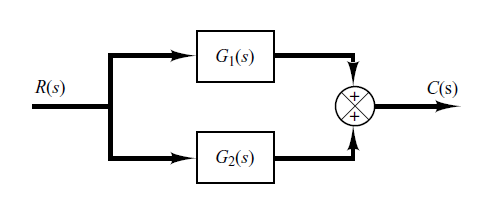

In this figure system $G_1(s)$ (which is represenr by sys1) and $G_2(s)$ (which is represenr by sys2) are Parallel connected system.

sys1=tf(num1,den1)

sys2=tf(num2,den2)

Then the parallel connected system $G_1(s)+G_2(s)$ can be given by

sys=parallel(sys1,sys2)


$$G_1(s)=\frac{10}{s^2+2s+10}$$


                                                   
$$G_2(s)=\frac{5}{s+5}$$


num1=[10];
den_r=[1 2 10];
num2=[5];
den2=[1 5];
sys1=tf(num1,den_r);
sys2=tf(num2,den2);
sysp=parallel(sys1,sys2)


sysp =
 
    5 s^2 + 20 s + 100
  -----------------------
  s^3 + 7 s^2 + 20 s + 50
 
Continuous-time transfer function.



[num,den]=parallel(num1,den_r,num2,den2);
printsys(num,den)

 
num/den = 
 
      5 s^2 + 20 s + 100
   -----------------------
   s^3 + 7 s^2 + 20 s + 50


If the system $G_1(s)$ and $G_2(s)$ are given by state space form then their MATLAB represntation are respectively

sys1=ss(A1,B1,C1,D1)

sys2=ss(A2,B2,C2,D2)

The parallel connected system $G_1(s)+G_2(s))$ is given by

sys=parallel(sys1,sys2)

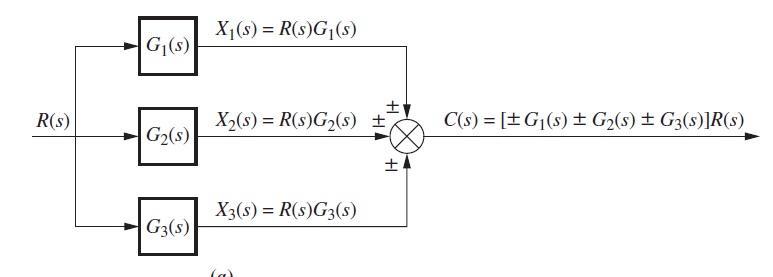

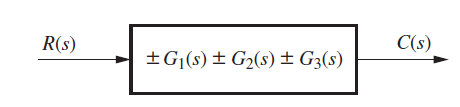


$$\mathrm{sys}=\mathrm{parallel}\left({\pm G}_1 \left(s\right)\pm G_2 \left(s\right)\pm G_3 \left(s\right)\right)$$


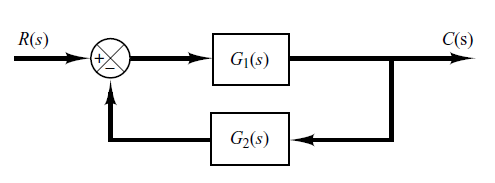

For this feedback system $G_1(s)$(which is sys1) is a feed forward path and $G_2(s)$(which is sys2) is feedback path.

sys1=tf(num1,den1)

sys2=tf(num2,den2)

Then the parallel connected system $G(s)=\frac{G_1(s)}{1+G_1(s)G_2(s)$ can be given by

sys=feedback(sys1,sys2)


$$G_1(s)=\frac{10}{s^2+2s+10}$$


                                                   
$$G_2(s)=\frac{5}{s+5}$$


num1=[10];
den_r=[1 2 10];
num2=[5];
den2=[1 5];
sys1=tf(num1,den_r);
sys2=tf(num2,den2);
sysf=feedback(sys1,sys2)


sysf =
 
         10 s + 50
  ------------------------
  s^3 + 7 s^2 + 20 s + 100
 
Continuous-time transfer function.



[num,den]=feedback(num1,den_r,num2,den2);
printsys(num,den)

 
num/den = 
 
           10 s + 50
   ------------------------
   s^3 + 7 s^2 + 20 s + 100


Note that in treating the feedback system Matlab assumed that the feedback was negative.If the system involves a positive feedback we need to add it in the argument  of feedback as follows

sys=feedback(sys1,sys2,+1)

Alternatively

sys=feedback(sys1,-sys2)

## Pole -Zero cancellation


$$\frac{C(s)}{R(s)}=\frac{s^2+3s+2}{s^3+8s^2+19s+12}$$



$$\frac{C(s)}{R(s)}=\frac{(s+1)(s+2)}{(s+3)(s+4)(s+1)}$$


Clearly (s+1) in the numerator and (s+1) in the denominator cancel each other.To obtain the minimal order transfer function for C(s)/R(s) we use command ''minreal(sys)''

num=[1 3 2];
den=[1 8 19 12];
sys=tf(num,den)


sys_r =
 
       s^2 + 3 s + 2
  -----------------------
  s^3 + 8 s^2 + 19 s + 12
 
Continuous-time transfer function.



sys_min=minreal(sys)


sys_min =
 
      s + 2
  --------------
  s^2 + 7 s + 12
 
Continuous-time transfer function.



The standard second order system is

 
$$$G(s)=\frac{\omega_n^2}{s^2+2\zeta \omega_n s+\omega_n^2}$$$


wn=5;
damping_ratio=0.4;
[num0,den]=ord2(wn,damping_ratio)

num0 = 1

den =      1     4    25


num=wn^2*num0;
printsys(num,den)

 
num/den = 
 
         25
   --------------
   s^2 + 4 s + 25


## Step Response

If the system numerato and denominator are known we may define the system by

sys=tf(num,den)

Then command such as

step(num,den)  OR step(sys)

or

If we define the time interval then

y=step(sys,t)

or

y=step(num,den,t)

plot(t,y)


$$\frac{C(s)}{R(s)}=\frac{2s+25}{s^2+4s+25}$$


num=[2 25];
den=[1 4 25];
sys=tf(num,den)


sys =
 
     2 s + 25
  --------------
  s^2 + 4 s + 25
 
Continuous-time transfer function.



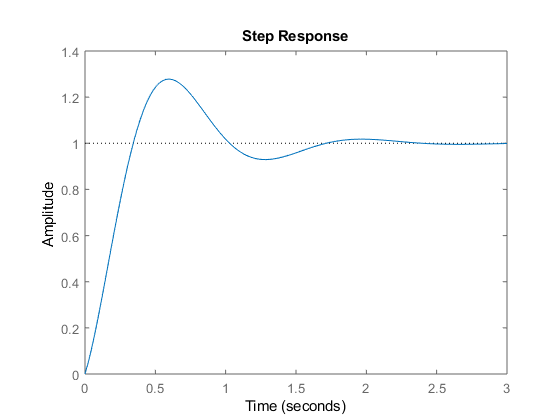

step(sys)

 
$$$\frac{C(s)}{R(s)}=\frac{20s+100}{10s^2+20s+100}$$$


=> $$\frac{C(s)}{R(s)}=\frac{2s+10}{s^2+2s+10}$$

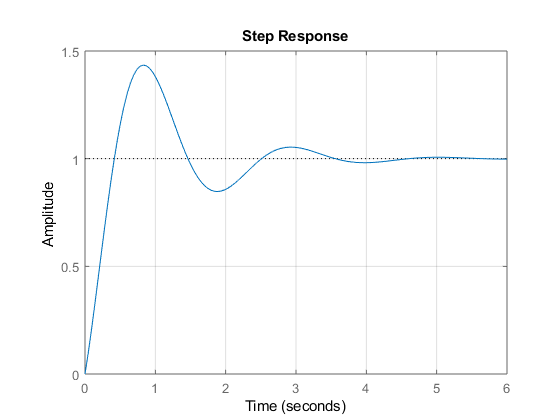

num=[2 10];
den=[1 2 10];
sys=tf(num,den);
step(sys)
grid on

In this plot the duration of this plot title, xlabel, ylabel automatically determined by MATLAB.If we wish to compute and plot the curve every 0.01 sec over the interval $0\le t\le 8$ The code is given below

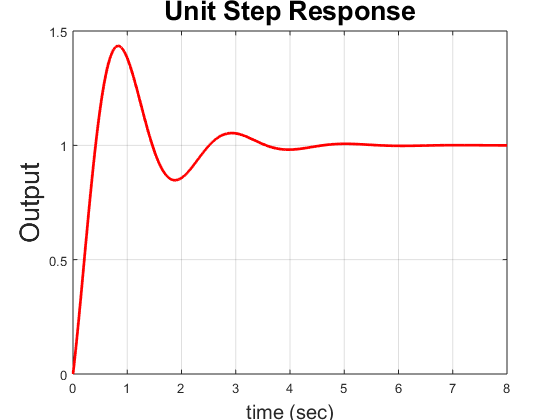

t=0:0.01:8;
num=[2 10];
den=[1 2 10];
sys=tf(num,den);
%step(sys,t)
%OR
y=step(sys,t);
plot(t,y,'r','LineWidth',2)
grid on
title('Unit Step Response','Fontsize',20);
xlabel('time (sec)','FontSize',15);
ylabel('Output','FontSize',20);

In state space representation system can be represent by

sys=ss(A,B,C,D)

step(sys)

or

step(A,B,C,D,iu)

 
$$$\frac{d}{dt} \pmatrix{x_1(t) \cr x_2(t)}=\pmatrix{-1 &-1 \cr 6.5 & 0} \pmatrix{x_1(t) \cr x_2(t)}+\pmatrix{1 & 1 \cr 1 & 0}\pmatrix{u_(t) \cr u_2(t)}$$$


 
$$$\pmatrix{y_1(t) \cr y_2(t)}=\pmatrix{1 & 0 \cr 0&1} \pmatrix{x_1(t) \cr x_2(t)}+\pmatrix{0&0 \cr 0 & 0}\pmatrix{u_1(t) \cr u_2(t)}$$$



$$$\pmatrix{Y_1(s) \cr Y_s(t)}=\pmatrix{\frac{s-1}{s^2+s+6.5} & \frac{s}{s^2+s+6.5} \cr \frac{s+7.5}{s^2+s+6.5} &\frac{6.5}{s^2+s+6.5}} \pmatrix{U_1(s) \cr U_2(s)}$$$


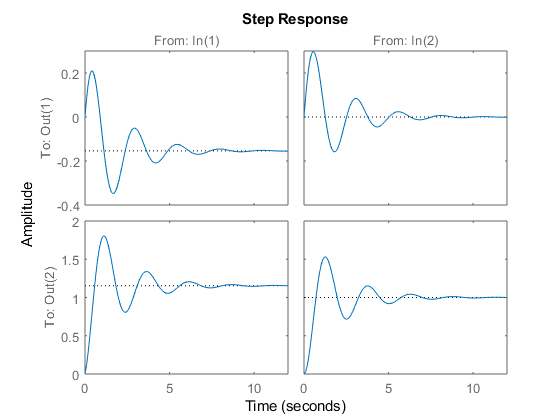

A=[-1 -1;6.5 0];
B=[1 1;1 0];
C=[1 0;0 1];
D=[0 0;0 0];
step(A,B,C,D);

Since the system involves with two input and two output four transfer function may be defined depending on which signal cosidered as input and output.When considering $u_1(t)$ is input we assume that signal $u_2(t)$ is zero.The four transfer function are


$$\frac{Y_1(s)}{U_1(s)}=\frac{s-1}{s^2+s+6.5}$$



$$\frac{Y_1(s)}{U_2(s)}=\frac{s}{s^2+s+6.5}$$



$$\frac{Y_2(s)}{U_1(s)}=\frac{s+7.5}{s^2+s+6.5}$$



$$\frac{Y_2(s)}{U_2(s)}=\frac{6.5}{s^2+s+6.5}$$


To plot the step response curves for the input $u_1(t)$ in one diagram and another two step response curve in another diagram we may used

step(A,B,C,D,1) 

step(A,B,C,D,2) 

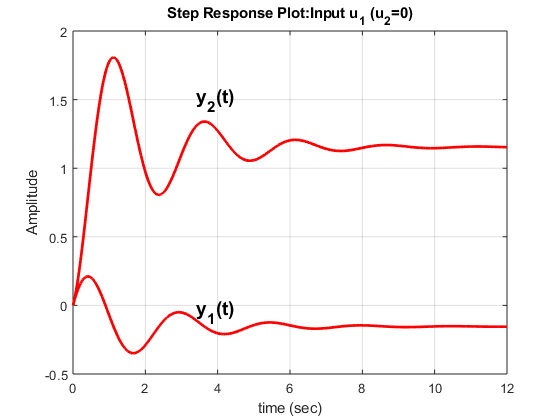

t=0:0.01:12;
y_u1=step(A,B,C,D,1,t);
plot(t,y_u1,'r','LineWidth',2)
grid on
title('Step Response Plot:Input u_1 (u_2=0)');
xlabel('time (sec)');
ylabel('Amplitude');
text(3.4,-0.05,'y_1(t)','FontWeight','bold','FontSize',14);
text(3.4,1.5,'y_2(t)','FontWeight','bold','FontSize',14);

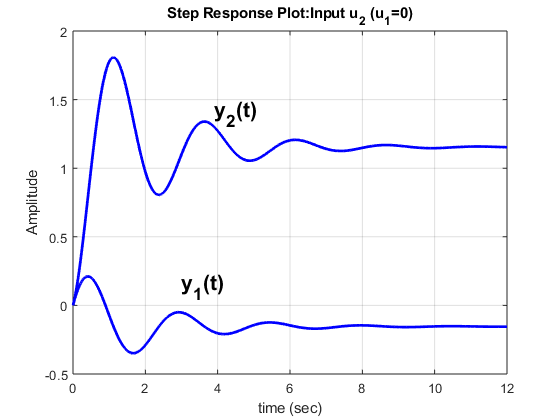


y_u2=step(A,B,C,D,1,t);
plot(t,y_u2,'b','LineWidth',2)
grid on
title('Step Response Plot:Input u_2 (u_1=0)');
xlabel('time (sec)');
ylabel('Amplitude');
text(3,0.14,'y_1(t)','FontWeight','bold','FontSize',16);
text(3.9,1.4,'y_2(t)','FontWeight','bold','FontSize',16);

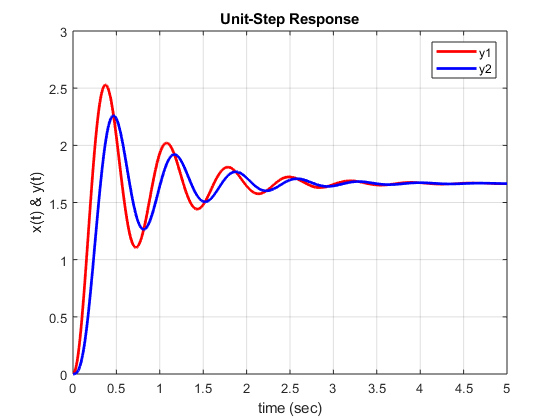

clear all
clc
t=0:0.01:5;
num1=[100 1000];
num3=[1000];
den=[1 10 100 600];
 
sys1=tf(num1,den);
sys2=tf(num3,den);
y1=step(sys1,t);
y2=step(sys2,t);
plot(t,y1,'r','LineWidth',2);
hold on
plot(t,y2,'b','LineWidth',2);
 
grid on
title('Unit-Step Response');
xlabel('time (sec)');
ylabel('x(t) & y(t)');
legend('y1','y2')

%str1='x(t)';
%str2='y(t)';
%gtext(str1,'Fontsize',20)
%gtext(str2,'fontsize',20);

## Obtain the output $c_r (t)$ when the input r(t) is Unit step and also obtain the output $c_d (t)$when the disturbance d(t) is Unit step.Assuming that r(t)=1(t) when d(t)=0 and vice versa

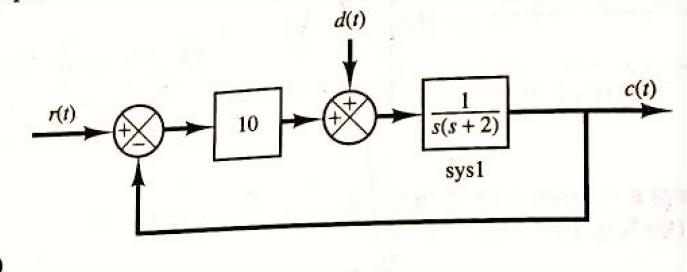

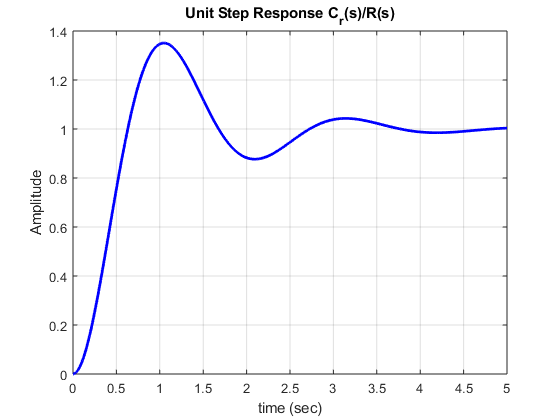

t=0:0.01:5;
num_r=1;
den_r=[1 2 0];
sys1=tf(num_r,den_r);
sys=feedback(10*sys1,1);
y=step(sys,t);
plot(t,y,'b','LineWidth',2);
grid on
title('Unit Step Response C_r(s)/R(s)');
xlabel('time (sec)');
ylabel('Amplitude');

To find the response $c_d (t)$ when d(t) is unit step the block diagram can be redrawn as

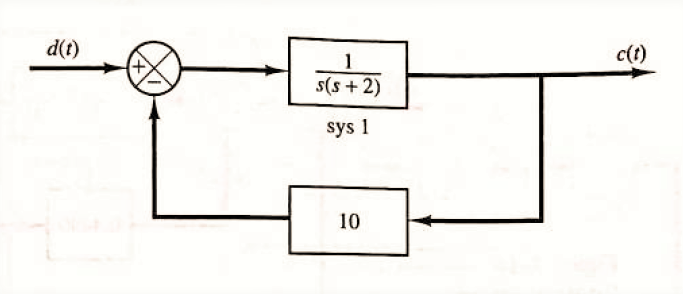

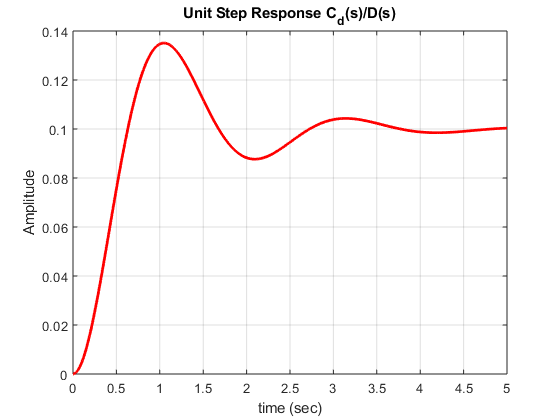

num_d=1;
den_d=[1 2 0];
sys2=tf(num_d,den_d);
sys_d=feedback(sys2,[10]);
y_d=step(sys_d,t);
plot(t,y_d,'r','LineWidth',2);
grid on
title('Unit Step Response C_d(s)/D(s)');
xlabel('time (sec)');
ylabel('Amplitude');

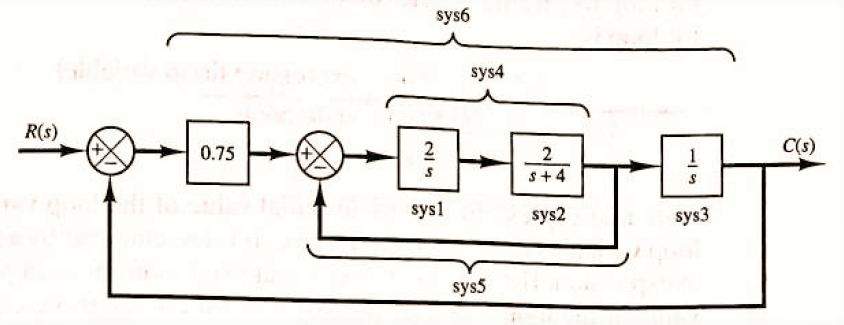

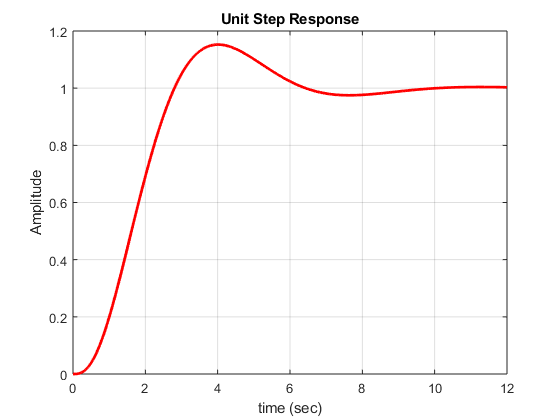

t=0:0.01:12;
num1=[2];
den1=[1 0];
sys1=tf(num1,den1);
num2=2;
den2=[1 4];
sys2=tf(num2,den2);
num3=1;
den3=[1 0];
sys3=tf(num3,den3);
sys4=series(sys1,sys2);
sys5=feedback(sys4,[1]);
sys6=feedback(0.75*sys5*sys3,[1]);
y=step(sys6,t);
plot(t,y,'r','LineWidth',2);
grid on
title('Unit Step Response');
xlabel('time (sec)');
ylabel('Amplitude');

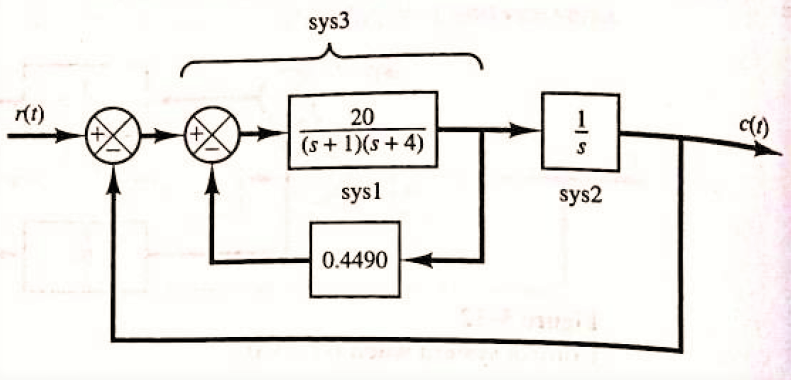

t=0:0.01:10;
num1=[20];
den1=[1 5 4];
sys1=tf(num1,den1);
num2=[1];
den2=[1 0];
sys2=tf(num2,den2);
sys3=feedback(sys1,0.4490);
sys=feedback(sys3*sys2,1)


sys =
 
              20
  --------------------------
  s^3 + 5 s^2 + 12.98 s + 20
 
Continuous-time transfer function.



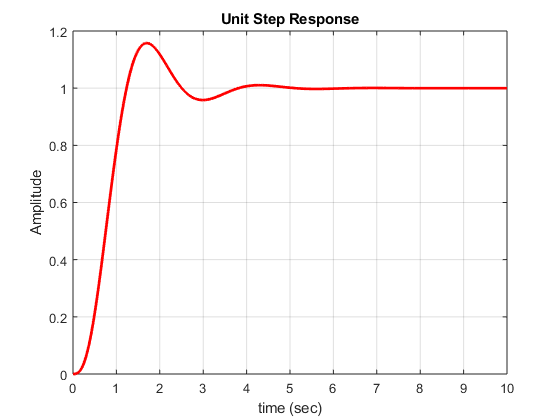

y=step(sys,t);
plot(t,y,'r','LineWidth',2);
grid on
title('Unit Step Response');
xlabel('time (sec)');
ylabel('Amplitude');

## Obtain the Partial fraction of C(s) when R(s) is Unit Step Function.


$$\frac{C(s)}{R(s)}=\frac{3s^3+25s^2+72s+80}{s^4+8s^3+40s^2+96s+80}$$


clear all
clc
t=0:0.01:5;
num=[3 25 72 80];
den=[1 8 40 96 80];
[r p, k]=residue(num,den)

r =    1.2500 - 0.7812i
   1.2500 + 0.7812i
   0.5000 + 0.0000i
   0.7500 + 0.0000i


p =   -2.0000 + 4.0000i
  -2.0000 - 4.0000i
  -2.0000 + 0.0000i
  -2.0000 + 0.0000i



k =

     []



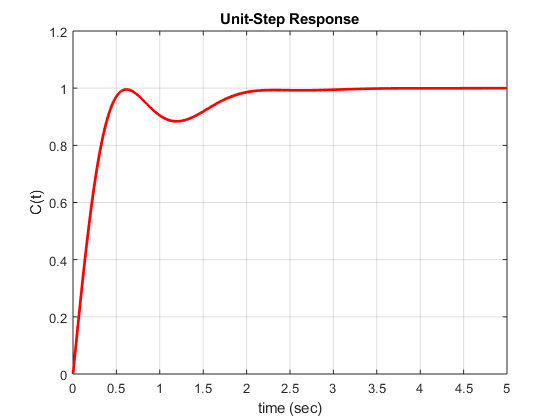

y=step(num,den,t);
clf
plot(t,y,'r','LineWidth',2);
title('Unit-Step Response');
xlabel('time (sec)');
ylabel('C(t)')
axis([0 5 0 1.2]);
grid on

## Repetitive Computations in MATLAB

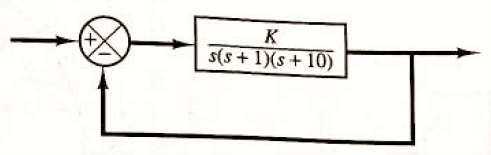

Determine the step response for k=1,2,3

t=0:0.01:20;
k=[5 10 20];
clf
for n=1:3;
    num=k(n);
    den=[1 10 11 0];
    sys1=tf(num,den)
    sys=feedback(sys1,1);
    y=step(sys,t);
    plot(t,y,'linewidth',2)
    hold on
end


sys1 =
 
           5
  -------------------
  s^3 + 10 s^2 + 11 s
 
Continuous-time transfer function.




sys1 =
 
          10
  -------------------
  s^3 + 10 s^2 + 11 s
 
Continuous-time transfer function.




sys1 =
 
          20
  -------------------
  s^3 + 10 s^2 + 11 s
 
Continuous-time transfer function.



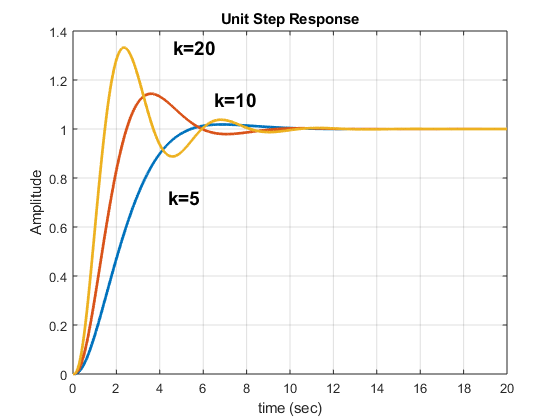

grid on
title('Unit Step Response');
xlabel('time (sec)');
ylabel('Amplitude');
text(4.6,1.33,'k=20','FontWeight','bold','FontSize',14);
text(6.5,1.12,'k=10','FontWeight','bold','FontSize',14);
text(4.4,0.72,'k=5','FontWeight','bold','FontSize',14);

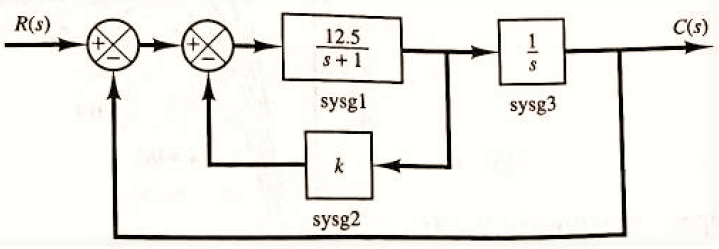

Determine the step response when feedback variable k=0.1, 0.2, 0.3, 0.4, 0.5

t=0:0.01:5;
k=[0.1 0.2 0.3 0.4 0.5];
clf
for n=1:5;
    numg1=12.5;
    deng1=[1 1];
    sysg1=tf(numg1,deng1);
    
    sysg2=k(n);
    numg3=[1];
    deng3=[1 0];
    sysg3=tf(numg3,deng3)
    
    sys1=feedback(sysg1,sysg2);
    
    sys2=series(sys1,sysg3);
    
    sys=feedback(sys2,1);
    
    y=step(sys,t);
    plot(t,y,'linewidth',2.5)
    hold on
end


sysg3 =
 
  1
  -
  s
 
Continuous-time transfer function.




sysg3 =
 
  1
  -
  s
 
Continuous-time transfer function.




sysg3 =
 
  1
  -
  s
 
Continuous-time transfer function.




sysg3 =
 
  1
  -
  s
 
Continuous-time transfer function.




sysg3 =
 
  1
  -
  s
 
Continuous-time transfer function.



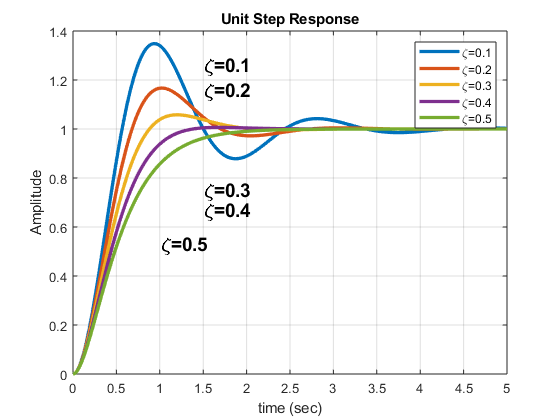

grid on
title('Unit Step Response');
xlabel('time (sec)');
ylabel('Amplitude');
text(1.51,1.26,'\zeta=0.1','FontWeight','bold','FontSize',14);
text(1.51,1.16,'\zeta=0.2','FontWeight','bold','FontSize',14);
text(1.51,0.75,'\zeta=0.3','FontWeight','bold','FontSize',14);
text(1.51,0.67,'\zeta=0.4','FontWeight','bold','FontSize',14);
text(1.01,0.53,'\zeta=0.5','FontWeight','bold','FontSize',14);
legend('\zeta=0.1','\zeta=0.2','\zeta=0.3','\zeta=0.4','\zeta=0.5')

## Impulse Response

The Unit Impulse Response of a system may be obtained following one of those command

impulse(num,den) or impulse(sys)

impulse(A,B,C,D)

impulse(num,den,t) or impulse(sys,t)

y=impulse(num,den) or y=impulse(sys)

[y,t]=impulse(num,den,t) or [y,t]=impulse(sys,t)

[[y,x,t]=impulse(num,den)](file:///D:/L-3%20T-2/Control%20System/Control%20system%20MATLAB/MATLAB%20for%20Control%20Engineers%20by%20Katsuhiko%20Ogata%20(z-lib.org).pdf) Ogata Page 118

[y,x,t]=impulse(num,den,t)

[y,x,t]=impulse(A,B,C,D)

[y,x,t]=impulse(A,B,C,D,iu)

[y,x,t]=impulse(A,B,C,D,iu,t)

## Obtain the Unit Impulse Response of the following system

 
$$$\frac{d}{dt} \pmatrix{x_1(t) \cr x_2(t)}=\pmatrix{0 &1 \cr -1 & -1} \pmatrix{x_1(t) \cr x_2(t)}+\pmatrix{0 \cr 1}u(t)$$$


 
$$$y(t)=[\matrix{1 & 0}]\pmatrix{x_1(t) \cr x_2(t)}+[\matrix{0}]u(t)$$$


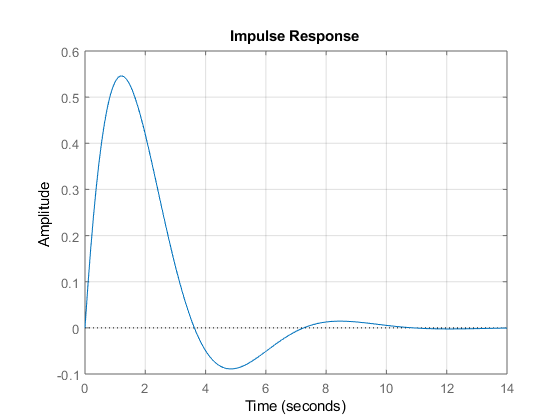

A=[0 1;-1 -1];
B=[0;1];
C=[1 0];
D=[0];
clf
impulse(A,B,C,D)
grid on

**Obtain the impulse response of the system**


$$G(s)=\frac{1}{s^2+0.2s+1}$$


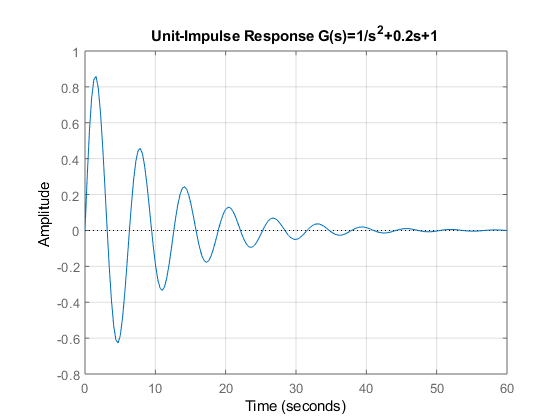

num=1;
den=[1 0.2 1];
clf
impulse(num,den)
grid
title('Unit-Impulse Response G(s)=1/s^2+0.2s+1')

## Alternative approach to obtained the unit impulse response

When the initial condition are zero the Unit Impulse response of G(s) is the same as Unit step response of sG(s)

 
$$G(s)=\frac{s}{s^2+0.2s+1} \frac{1}{s}$$


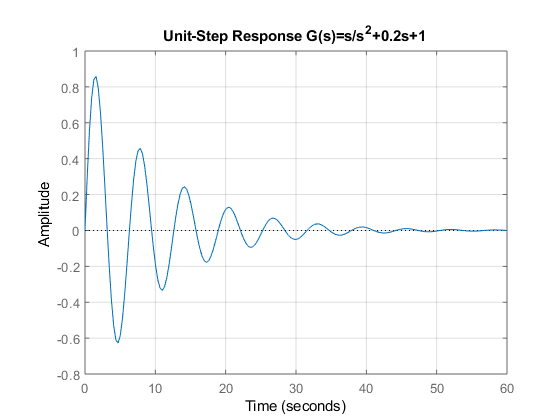

num=[1 0];
den=[1 0.2 1];
clf
step(num,den)
grid
title('Unit-Step Response G(s)=s/s^2+0.2s+1')

## Ramp Response

There is no ramp command in MATLAB. To obtain the ramp response of transfer function G(s) with zero initial condition divide G(s) by s and then use step command.

For unite ramp function $R(s)=\frac{1}{s^2}$


$$\frac{C(s)}{R(s)}=\frac{1}{s^2+s+1}$$



$$C(s)=\frac{1}{s^2+s+1} \frac{1}{s^2}$$



$$C(s)=\frac{1}{(s^2+s+1)s}\frac{1}{s}$$


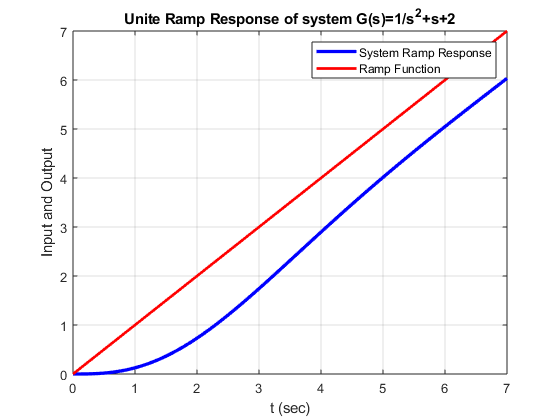

num=[1];
den=[1 1 1 0];
t=0:0.1:7;
y=step(num,den,t);
clf
plot(t,y,'b','LineWidth',2.5);
hold on
plot(t,t,'r','linewidth',2);
grid
title('Unite Ramp Response of system G(s)=1/s^2+s+2')
xlabel('t (sec)');
ylabel('Input and Output');
legend('System Ramp Response','Ramp Function');

When the closed loop system involves with numerator dyhamics the unet step responsw mat exhibit a large overshoot.Obtain Ramp Response


$$\frac{C(s)}{R(s)}=\frac{10s+4}{s^2+4s+4}$$



$$C(s)=\frac{10s+4}{s^2+4s+4} \frac{1}{s^2}$$



$$C(s)=\frac{10s+4}{(s^2+4s+4){s}} \frac{1}{s}$$



$$C(s)=\frac{10s+4}{s^3+4s^2+4s}$$


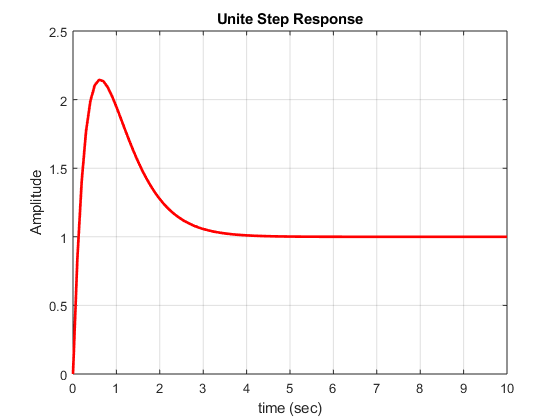

num1=[10 4];
den1=[1 4 4];
t=0:0.1:10;
y1=step(num1,den1,t);
clf
plot(t,y1,'r','LineWidth',2);
grid
xlabel('time (sec)');
ylabel('Amplitude');
title('Unite Step Response');

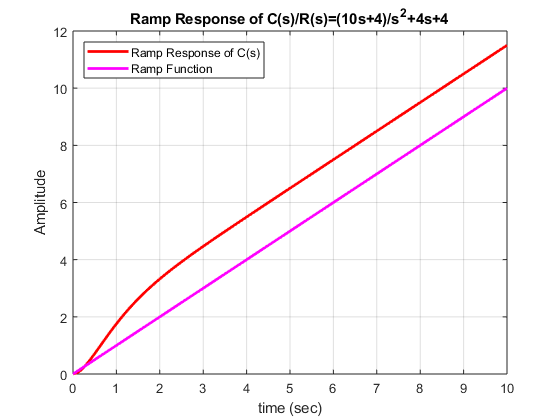

num2=[10 4];
den2=[1 4 4 0];
t=0:0.1:10;
y2=step(num2,den2,t);
clf
plot(t,y2,'r','LineWidth',2);
hold on
plot(t,t,'m','LineWidth',2);
grid
xlabel('time (sec)');
ylabel('Amplitude');
tiystle('Ramp Response of C(s)/R(s)=(10s+4)/s^2+4s+4');
legend('Ramp Response of C(s)','Ramp Function','Location','northwest')

Notice that the Unite step response curve exhibit over 115% of overshoot.The unite  ramp reponse curve leads the input curve.The phenomena occured the presence of a large derivative term in the numerator.

## Response to arbitary input

To obatain the response of time invariant system for any arbitary input we can used lsim command

lsim(num,den,u,t)

lsim(sys,u,t)

lsim(A,B,C,D,u,t)

y=lsim(num,den,u,t)

y=lsim(sys,u,t)

y=lsim(A,B,C,D,u,t)

If the initial condition are nonzero in state space model then command are

lsim(sys,u,t,$x_0$)


$$\frac{C(s)}{R(s)}=\frac{1}{s^2+s+1}$$


Obtain the ramp response of this system by usihg lsim command

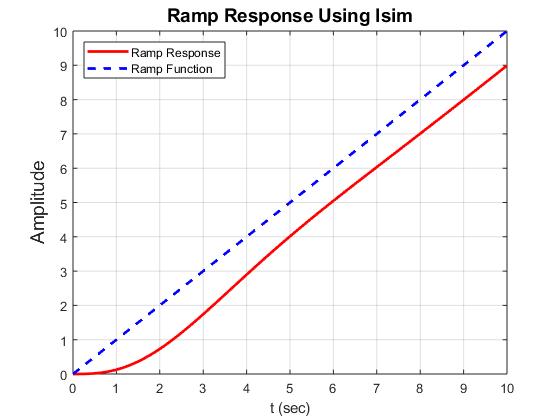


clf
num=1;
den=[1 1 1];
t=0:0.1:10;
ramp=t;
y=lsim(num,den,ramp,t);
plot(t,y,'r','LineWidth',2);
hold on
plot(ramp,t,'b--','LineWidth',2);
grid
title('Ramp Response Using lsim','FontSize',14)
xlabel('t (sec)');
ylabel('Amplitude','FontSize',14);
legend('Ramp Response','Ramp Function','Location','northwest')

 
$$$\frac{d}{dt} \pmatrix{x_1(t) \cr x_2(t)}=\pmatrix{-1 &0.5 \cr -1 & 0} \pmatrix{x_1(t) \cr x_2(t)}+\pmatrix{ 0 \cr 1}{u_(t)$$$


y=$\pmatrix{1 &0}\pmatrix{x_1(t ) \cr x_2(t)}$

Obtain the response curve y(t) when u(t) is

- u(t)=Unit step input

- u(t)=exp(-t)

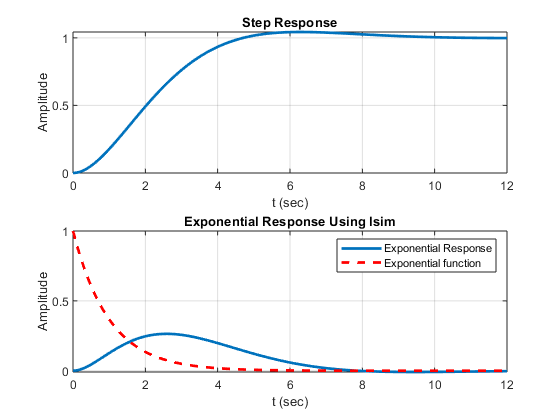

clf
t=0:0.1:12;
A=[-1,0.5;-1 0];
B=[0;1];
C=[1,0];
D=[0];
y1=step(A,B,C,D,1,t);
subplot(2,1,1);
plot(t,y1,'LineWidth',2);
grid
title('Step Response','FontSize',14)
xlabel('t (sec)');
ylabel('Amplitude','FontSize',14);

exp=exp(-t);
y2=lsim(A,B,C,D,exp,t);
subplot(2,1,2);
plot(t,y2,'LineWidth',2);
hold on
plot(t,exp,'r--','LineWidth',2);
grid
title('Exponential Response Using lsim','FontSize',14)
xlabel('t (sec)');
ylabel('Amplitude','FontSize',14);
legend('Exponential Response','Exponential function');

## Using lsim obtain the unit ramp[ response


$$\frac{C(s)}{R(s)}=\frac{s+10}{s^3+6s^2+9s+10}$$


also obtain the response when input is 2exp(-0.5t)

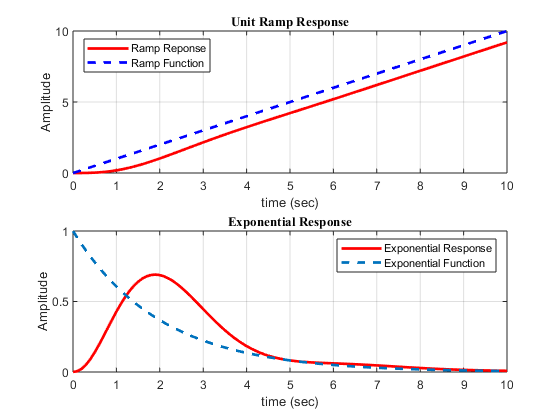

clf
clear all
t=0:0.1:10;
ramp=t;
fun=exp(-0.5*t);
num=[1 10];
den=[1 6 9 10];
y=lsim(num,den,ramp,t);
subplot(2,1,1)
plot(t,y,'r','LineWidth',2);
hold on
plot(t,ramp,'b--','LineWidth',2);
xlabel('time (sec)');
ylabel('Amplitude');
title('Unit Ramp Response','FontName','times','FontSize',14);
grid
legend('Ramp Reponse','Ramp Function','Location','northwest')

z=lsim(num,den,fun,t);
subplot(2,1,2)
plot(t,z,'r','LineWidth',2);
hold on
plot(t,fun,'LineStyle','--','LineWidth',2);
xlabel('time (sec)');
ylabel('Amplitude');
title('Exponential Response','FontName','times','FontSize',14);
grid
legend('Exponential Response','Exponential Function')

## Response to arbitary initial condition

## Three Dimentional Plot

## Addition of pole to the forward path Transfer function Unity feedback system

clear all
w=1;
l=1;
clf
for Tp=[0 1 2 5];
    t=0:0.001:50;
    num=[w];
    den=[Tp 1+2*l*w*Tp 2*l*w w^2];
    roots(den)
    step(num,den,t);
    hold on
end

ans =     -1
    -1


ans =   -2.3247 + 0.0000i
  -0.3376 + 0.5623i
  -0.3376 - 0.5623i


ans =   -2.1421 + 0.0000i
  -0.1789 + 0.4488i
  -0.1789 - 0.4488i


ans =   -2.0526 + 0.0000i
  -0.0737 + 0.3033i
  -0.0737 - 0.3033i


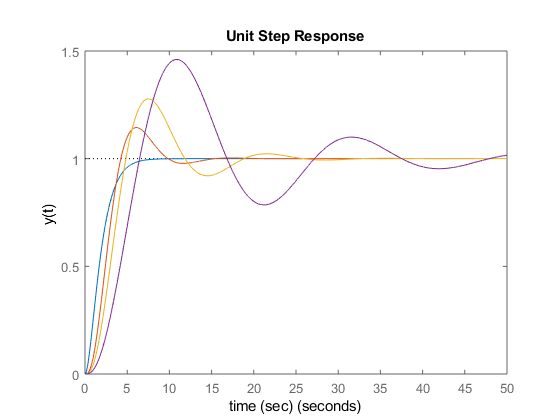

title('Unit Step Response');
xlabel('time (sec)');
ylabel('y(t)')